## Linear Parametrization

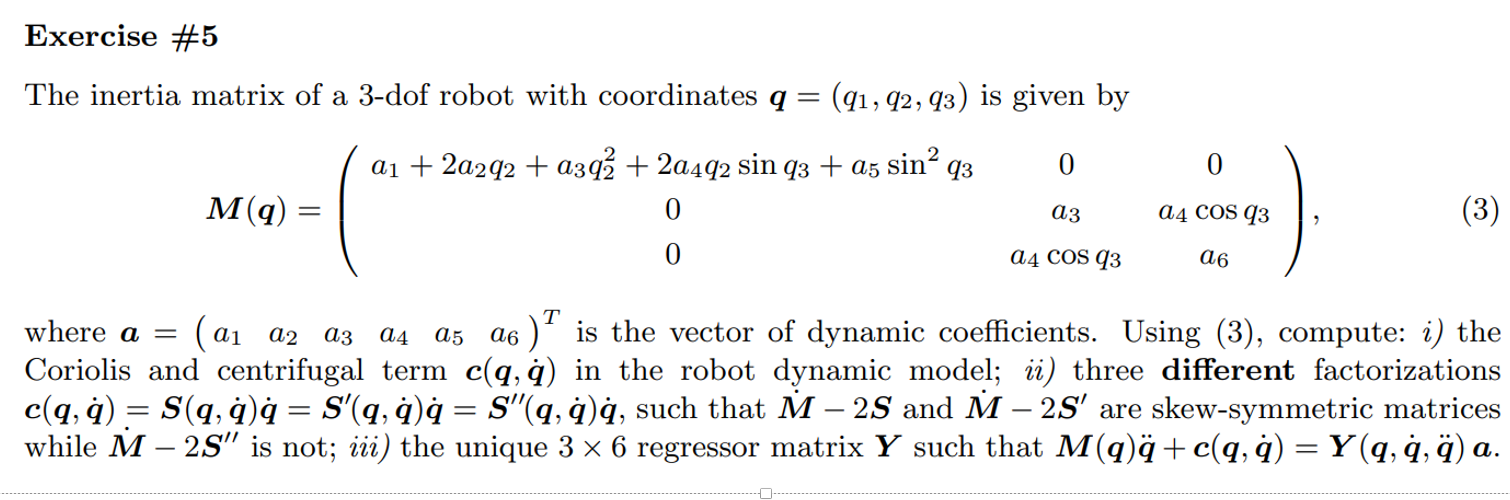

### Point 1

Compute Coriolis and centrifugal term

syms q1 q2 q3 dq1 dq2 dq3 m1 m2 m3 a1 a2 a3 a4 a5 a6 ddq1 ddq2 ddq3 real

% Inertia Matrix 
M = [a1+2*a2*q2+a3*q2^2+2*a4*q2*sin(q3)+a5*(sin(q3))^2    0           0;
                       0                                  a3      a4*cos(q3);
                       0                               a4*cos(q3)    a6;];

% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2; q3;];
dq = [dq1; dq2; dq3;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(3,3));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:3
    for j = 1:3
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:3
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = C * dq;

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\begin{array}{l} \left(\begin{array}{ccc} {\mathrm{dq}}_{2}\,\left(a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\right)+{\mathrm{dq}}_{3}\,\left(a_{4}\,q_{2}\,\cos\left(q_{3}\right)+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right) & {\mathrm{dq}}_{1}\,\left(a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\right) & \sigma_{1}\\ -{\mathrm{dq}}_{1}\,\left(a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\right) & 0 & -a_{4}\,{\mathrm{dq}}_{3}\,\sin\left(q_{3}\right)\\ -\sigma_{1} & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1}\,\left(\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2}+a_{4}\,q_{2}\,\cos\left(q_{3}\right)\right) \end{array}$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sigma_{2}+{\mathrm{dq}}_{3}\,\left(a_{4}\,q_{2}\,\cos\left(q_{3}\right)+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right)\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sigma_{1}+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sigma_{2}\\ \left(-a_{2}-a_{3}\,q_{2}-a_{4}\,\sin\left(q_{3}\right)\right)\,{{\mathrm{dq}}_{1}}^{2}-a_{4}\,\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{3}}^{2}\\ -{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2}+a_{4}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right) \end{array}$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\begin{array}{l} \left(\begin{array}{ccc} {\mathrm{dq}}_{2}\,\left(a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\right)+{\mathrm{dq}}_{3}\,\left(a_{4}\,q_{2}\,\cos\left(q_{3}\right)+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right) & {\mathrm{dq}}_{1}\,\left(a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\right) & \sigma_{1}\\ -{\mathrm{dq}}_{1}\,\left(a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\right) & 0 & -a_{4}\,{\mathrm{dq}}_{3}\,\sin\left(q_{3}\right)\\ -\sigma_{1} & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1}\,\left(\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2}+a_{4}\,q_{2}\,\cos\left(q_{3}\right)\right) \end{array}$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sigma_{2}+{\mathrm{dq}}_{3}\,\left(a_{4}\,q_{2}\,\cos\left(q_{3}\right)+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right)\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sigma_{1}+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sigma_{2}\\ \left(-a_{2}-a_{3}\,q_{2}-a_{4}\,\sin\left(q_{3}\right)\right)\,{{\mathrm{dq}}_{1}}^{2}-a_{4}\,\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{3}}^{2}\\ -{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2}+a_{4}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right) \end{array}$$

### Point 3

Compute the Regressor matrix

ddq = [ddq1; ddq2; ddq3;];
app = M*ddq + c_vec;
disp('Sum of M*ddq + c_vec');

Sum of M*ddq + c_vec


disp(app);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sigma_{2}+{\mathrm{dq}}_{3}\,\left(\sigma_{1}+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right)\right)+{\mathrm{ddq}}_{1}\,\left(a_{3}\,{q_{2}}^{2}+2\,a_{4}\,q_{2}\,\sin\left(q_{3}\right)+2\,a_{2}\,q_{2}+a_{5}\,{\sin\left(q_{3}\right)}^{2}+a_{1}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\left(\sigma_{3}+\sigma_{1}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sigma_{2}\\ \left(-a_{2}-a_{3}\,q_{2}-a_{4}\,\sin\left(q_{3}\right)\right)\,{{\mathrm{dq}}_{1}}^{2}-a_{4}\,\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{3}}^{2}+a_{3}\,{\mathrm{ddq}}_{2}+a_{4}\,{\mathrm{ddq}}_{3}\,\cos\left(q_{3}\right)\\ \left(-\sigma_{3}-\sigma_{1}\right)\,{{\mathrm{dq}}_{1}}^{2}+a_{6}\,{\mathrm{ddq}}_{3}+a_{4}\,{\mathrm{ddq}}_{2}\,\cos\left(q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\\ \sigma_{3}=\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2} \end{array}$$

ddq = [ddq1; ddq2; ddq3];
Ya = M*ddq + c_vec;   % (3x1)

% 5) Definisco il vettore dei simboli dinamici
dynamic_symbols = [a1, a2, a3, a4, a5, a6];

% 6) Estraggo la matrice di regressione Y
Y = extract_Y_v3(Ya, dynamic_symbols);

disp('======== Risultati ========');

======== Risultati ========


disp('Matrice di inerzia M(q):');

Matrice di inerzia M(q):


disp(M);

$$\left(\begin{array}{ccc} a_{3}\,{q_{2}}^{2}+2\,a_{4}\,q_{2}\,\sin\left(q_{3}\right)+2\,a_{2}\,q_{2}+a_{5}\,{\sin\left(q_{3}\right)}^{2}+a_{1} & 0 & 0\\ 0 & a_{3} & a_{4}\,\cos\left(q_{3}\right)\\ 0 & a_{4}\,\cos\left(q_{3}\right) & a_{6} \end{array}\right)$$

disp('Vettore di Coriolis c_vec:');

Vettore di Coriolis c_vec:


disp(c_vec);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sigma_{2}+{\mathrm{dq}}_{3}\,\left(a_{4}\,q_{2}\,\cos\left(q_{3}\right)+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right)\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sigma_{1}+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sigma_{2}\\ \left(-a_{2}-a_{3}\,q_{2}-a_{4}\,\sin\left(q_{3}\right)\right)\,{{\mathrm{dq}}_{1}}^{2}-a_{4}\,\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{3}}^{2}\\ -{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2}+a_{4}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right) \end{array}$$

disp('Espressione dinamica Ya (M*ddq + c):');

Espressione dinamica Ya (M*ddq + c):


disp(Ya);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sigma_{2}+{\mathrm{dq}}_{3}\,\left(\sigma_{1}+a_{5}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\right)\right)+{\mathrm{ddq}}_{1}\,\left(a_{3}\,{q_{2}}^{2}+2\,a_{4}\,q_{2}\,\sin\left(q_{3}\right)+2\,a_{2}\,q_{2}+a_{5}\,{\sin\left(q_{3}\right)}^{2}+a_{1}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\left(\sigma_{3}+\sigma_{1}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sigma_{2}\\ \left(-a_{2}-a_{3}\,q_{2}-a_{4}\,\sin\left(q_{3}\right)\right)\,{{\mathrm{dq}}_{1}}^{2}-a_{4}\,\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{3}}^{2}+a_{3}\,{\mathrm{ddq}}_{2}+a_{4}\,{\mathrm{ddq}}_{3}\,\cos\left(q_{3}\right)\\ \left(-\sigma_{3}-\sigma_{1}\right)\,{{\mathrm{dq}}_{1}}^{2}+a_{6}\,{\mathrm{ddq}}_{3}+a_{4}\,{\mathrm{ddq}}_{2}\,\cos\left(q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{2}+a_{3}\,q_{2}+a_{4}\,\sin\left(q_{3}\right)\\ \sigma_{3}=\frac{a_{5}\,\sin\left(2\,q_{3}\right)}{2} \end{array}$$

disp('Matrice di regressione Y:');

Matrice di regressione Y:


disp(Y);

$$\left(\begin{array}{cccccc} {\mathrm{ddq}}_{1} & 2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}+2\,{\mathrm{ddq}}_{1}\,q_{2} & {\mathrm{ddq}}_{1}\,{q_{2}}^{2}+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,q_{2} & {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sin\left(q_{3}\right)+{\mathrm{dq}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{3}\right)+2\,{\mathrm{ddq}}_{1}\,q_{2}\,\sin\left(q_{3}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & {\mathrm{ddq}}_{1}\,{\sin\left(q_{3}\right)}^{2}+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sin\left(2\,q_{3}\right)}{2} & 0\\ 0 & -{{\mathrm{dq}}_{1}}^{2} & {\mathrm{ddq}}_{2}-{{\mathrm{dq}}_{1}}^{2}\,q_{2} & -\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}-\sin\left(q_{3}\right)\,{{\mathrm{dq}}_{3}}^{2}+{\mathrm{ddq}}_{3}\,\cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 0 & {\mathrm{ddq}}_{2}\,\cos\left(q_{3}\right)-{{\mathrm{dq}}_{1}}^{2}\,q_{2}\,\cos\left(q_{3}\right) & -\frac{{{\mathrm{dq}}_{1}}^{2}\,\sin\left(2\,q_{3}\right)}{2} & {\mathrm{ddq}}_{3} \end{array}\right)$$


%% =============== FUNZIONE DI ESTRAZIONE =================

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % Estrae la matrice di regressione Y da un'espressione Ya lineare
    % nei simboli elencati in dynamic_symbols.
    %
    % Ya              : espressione simbolica (ad es. M*ddq + c + G)
    % dynamic_symbols : array contenente [a1, a2, ..., aN]
    %
    % Output: Y       : matrice che, moltiplicata per [a1; a2; ...; aN],
    %                   restituisce l'originale Ya.

    % Inizializzazione
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    % Assicuriamoci di avere dynamic_symbols come array riga
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i = 1:Y_columns
        % Costruisco un array di sostituzione: tutti zeri tranne un 1
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        % Sostituisco in Ya: a_i=1, gli altri=0
        Yi = subs(Ya, dynamic_symbols, subs_array);

        % Concateno in colonna
        Y = [Y, Yi];
    end
end